# Transformaciones geométricas e interpolación

La **Image Processing Toolbox** permite realizar rotaciones, homotecia (zoom) y selección, así como operaciones más especializadas. 

Estas funciones soportan cualquier tipo de imagen, aunque se debe procesar cada una de las componentes de una imagen RGB por separado.

## Tipos de interpolación 

Permite realizar tres métodos de **interpolación**:

- Vecino más cercano

- Interpolación bilineal

- Interpolación bicúbica

Los comandos que se muestran a continuación crean una figura de dos picos que ilustra estas diferencias:

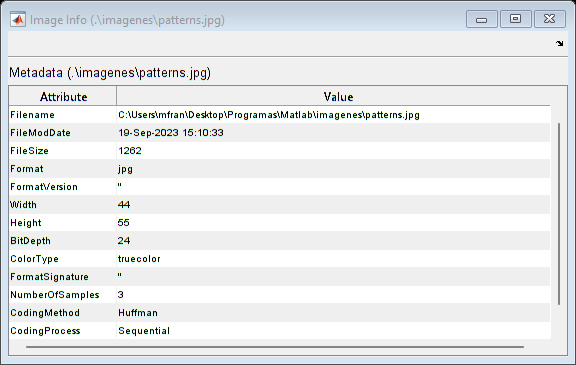

close all
clear all

I=imread('.\imagenes\patterns.jpg'); 
imageinfo('.\imagenes\patterns.jpg')

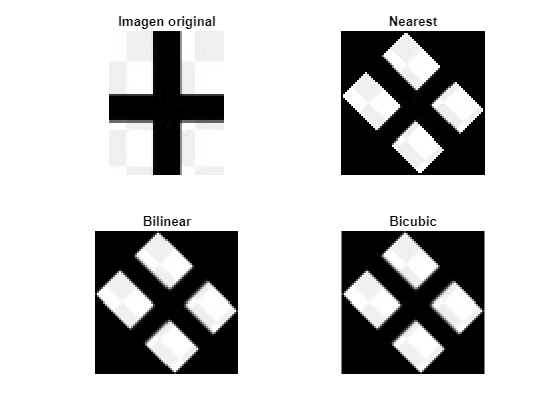

Y=imrotate(I,45, "nearest");
L=imrotate(I,45, "bilinear");
M=imrotate(I,45, "bicubic");

figure
subplot(2,2,1), imshow(I); title('Imagen original');
subplot(2,2,2), imshow(Y),title('Nearest'); 
subplot(2,2,3), imshow(L); title('Bilinear');
subplot(2,2,4), imshow(L); title('Bicubic');

**Ejecute este código y realice pruebas modificando el número de puntos intermedios.**

## **Rotación de imágenes**

El comando *imrotate* rota una imagen usando un método de interpolación especificado y un ángulo de rotación. Si no se especifica un método de interpolación, la función determina el tipo de imagen y automáticamente elige el mejor método. Cuando no se especifica el método de interpolación a *imrotate*, la función elige el mejor método para la imagen. 

Para rotar la imagen “trees” 35 º (“trees” es una imagen indexada, por lo que imrotate usa la **interpolación por vecino más cercano)**:

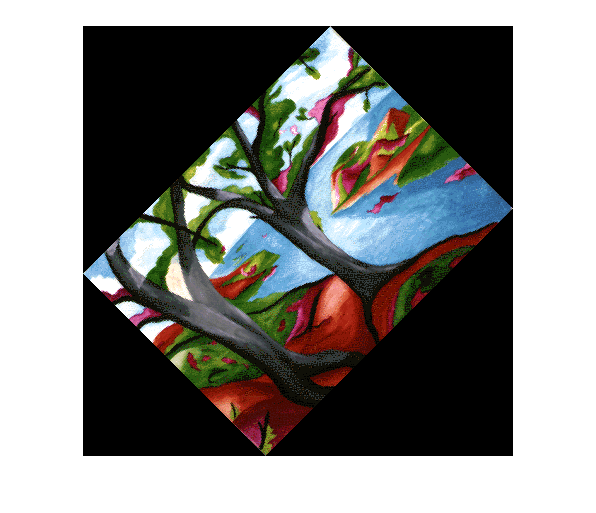

[X1,map]=imread (".\imagenes\trees.tif");
X=ind2rgb(X1,map);
Y=imrotate(X,45);
figure, imshow(Y);  

**Ejecute este código y pruebe diferentes ángulos.**

## Selección dentro de una imagen

La función *imcrop* extrae una porción rectangular de una imagen. *imcrop* permite definir el rectángulo de corte con el ratón o a través de una lista de argumentos. Por ejemplo, para extraer un rectángulo de 92x95 de la imagen “trees” comenzando en la coordenada (71,107), se utiliza:

[X1,map]=imread (".\imagenes\trees.tif");
X=ind2rgb(X1,map);
figure, subplot(1,2,1), imshow(X);
X2=imcrop(X);
subplot(1,2,2), imshow(X2);

Para definir el rectángulo de corte con el ratón, se usa  imcrop sin argumentos de entrada. La actual figura debe contener una imagen en la cual  *imcrop* pueda operar. Tras llamar a *imcrop*, presionar el botón izquierdo del ratón mientras se arrastra por la imagen visualizada. Soltar el botón del ratón cuando se haya definido el área deseada y al hacer doble click se copiará la parte seleccionada en otra figura.

**Ejecute el código anterior y realice una prueba modificando la posición y dimensiones del rectángulo y utilizando *****imcrop***** si argumentos de entrada.**

## Cambio de tamaño de imágenes

La función *imresize* cambia el tamaño o la relación de muestreo de una imagen, usando un método de interpolación especificado. Si no se especifica un método, la función determina el tipo de imagen y automáticamente elige el mejor. *imresize* puede recalibrar una imagen por un factor, o a un tamaño de fila-columna especificado. Si se reduce el tamaño de la imagen, *imresize* aplica un filtro paso bajo a la imagen antes de la interpolación. Esto reduce el efecto de las muestras de Moiré, rizados que resultan del aliasing durante el muestreo. Se puede aplicar la función *truesize* para recalibrar imágenes. Esta función visualiza una imagen con un pixel de pantalla por cada pixel de la imagen, así podemos ver el tamaño rea (si no, veremos todas aparentemente iguales, por el escalado que realiza Matlab para visualizar).

Por ejemplo, para recalibrar X a cuatro veces su actual tamaño usaremos,

%load trees   % carga el contenido del fichero trees.mat: X y map.
%X2=ind2rgb(X,map);
%Y1=imresize(X2,4);  % Si dejamos X como indexada: [Y,newmap]=imresize(X,map,2);

[X,map]=imread (".\imagenes\kids.tif");
[Y1,newmap1]=imresize(X,map,2);

Para obtener una imagen de tamaño 100x150 usaremos, 

%Y2=imresize(X2,[100 150]);
% Si X es indexada: [Y, newmap]=imresize(X,map,[100 150]);
[Y2, newmap2]=imresize(X,map,[100 150]);

Se puede comprobar el (nuevo) tamaño con el comando: 	

size(Y1)

ans =    800   636


size(Y2)

ans =    100   150


Se puede visualizar el resultado con:

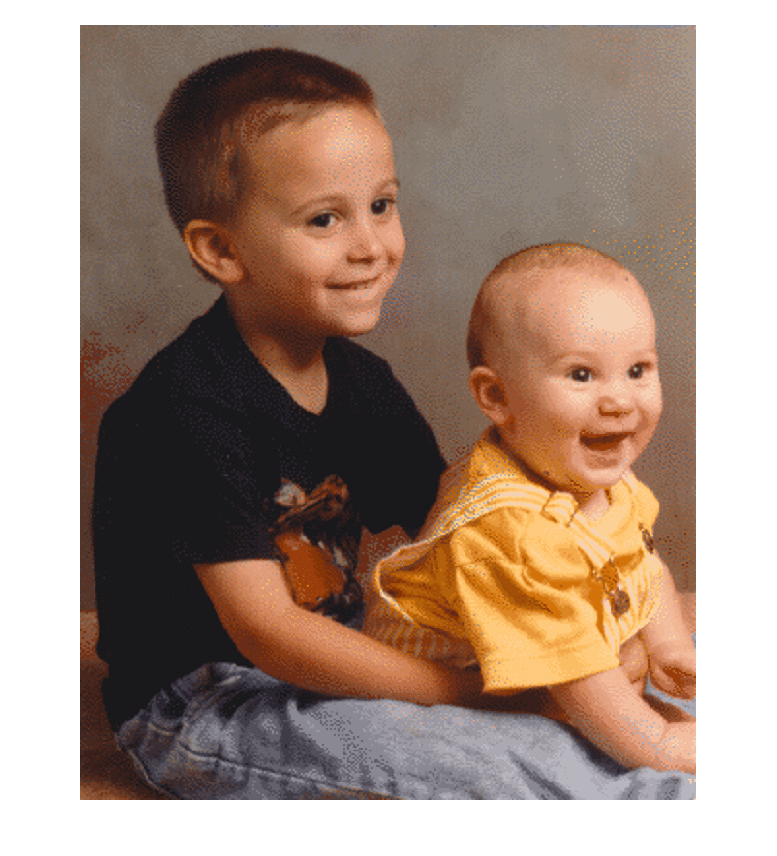

%figure;  imshow(Y1); truesize; % Si es indexada: imshow (Y, newmap); 
figure;  imshow(Y1, newmap1); truesize;

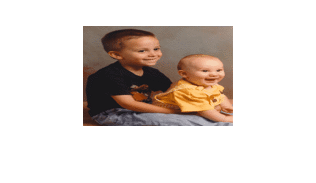


figure;  imshow(Y2, newmap2); truesize; 

**Ejecute el código anterior y realice diferentes pruebas cambiando tamaños y tipos de imágenes (indexada...).**

## Zoom de una imagen

En Matlab, una vez visualizada una imagen en una figura de Matlab se puede dentro del menú *Figure --> Tools --> zoom in* ampliar la imagen para ver mejor los detalles. 